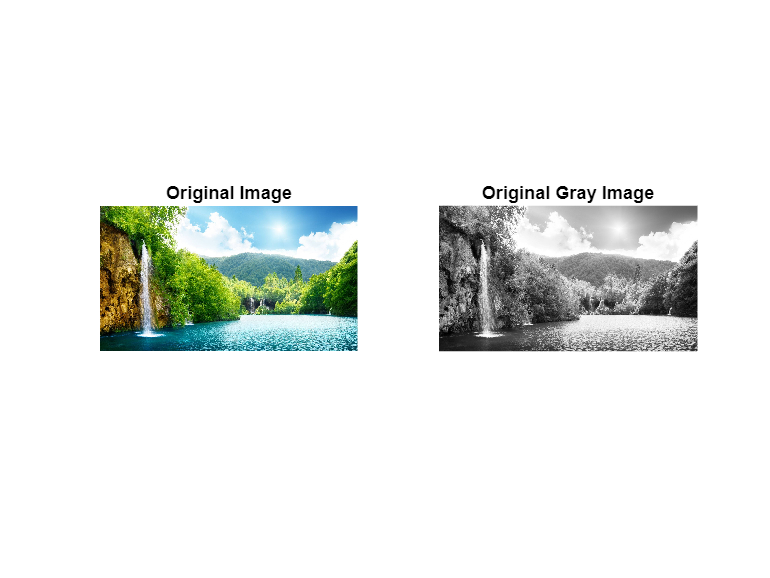

%read the image
img = imread("pic1.png");
% Convert image to grayscale
imgGray = im2gray(img);
figure;
subplot(1,2,1);
imshow(img);
title("Original Image");
subplot(1,2,2);
imshow(imgGray);
title("Original Gray Image");

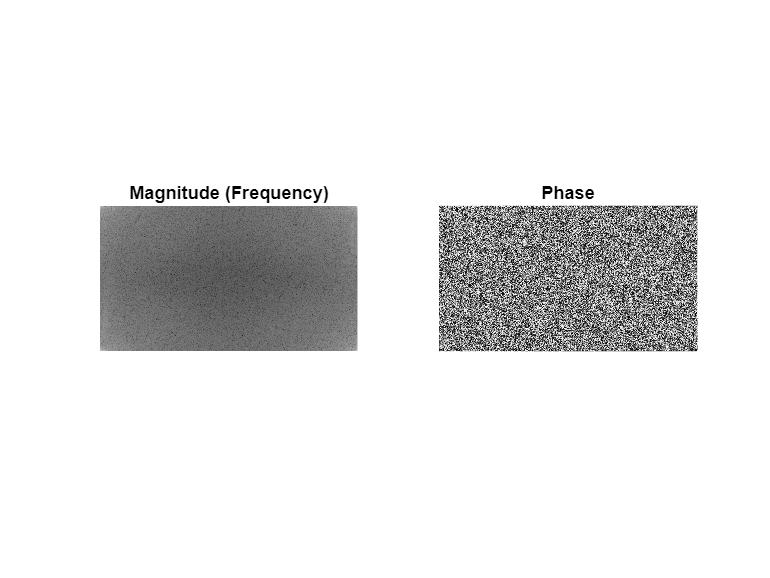

% Applying Fourier transform to the image
fourier_transform = fft2(imgGray);

% Calculating the magnitude and phase
magnitude = abs(fourier_transform);
phase = angle(fourier_transform);

% Display the frequency as an image
subplot(1,2,1);
imshow(log(1 + magnitude), []);
title('Magnitude (Frequency)');
% Display the phase as an image
subplot(1,2,2);
imshow(phase, []);
title('Phase');

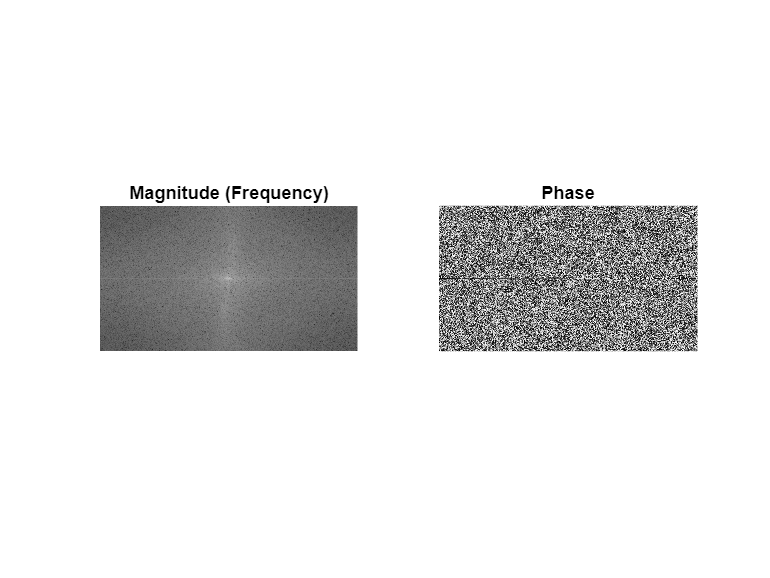

% Moving low frequency components to centre
ft_shift = fftshift(fourier_transform);
% Calculating the magnitude and phase
magnitude = abs(ft_shift);
phase = angle(ft_shift);

% Display the frequency as an image
subplot(1,2,1);
imshow(log(1 + magnitude), []);
title('Magnitude (Frequency)');
% Display the phase as an image
subplot(1,2,2);
imshow(phase, []);
title('Phase');

% Removing the low-frequency components
% Creating a mask with a high-pass filter
[m, n] = size(ft_shift);
[X, Y] = meshgrid(1:n, 1:m);
centerX = round(n/2);
centerY = round(m/2);
% Width of the Gaussian low pass filter
sigma = 10; 
GaussianFilter = exp(-((X-centerX).^2 + (Y-centerY).^2) / (2*sigma^2));
HighPassFilter = 1 - GaussianFilter;

% Apply the high-pass filter
ff_highpass = ft_shift .* HighPassFilter;

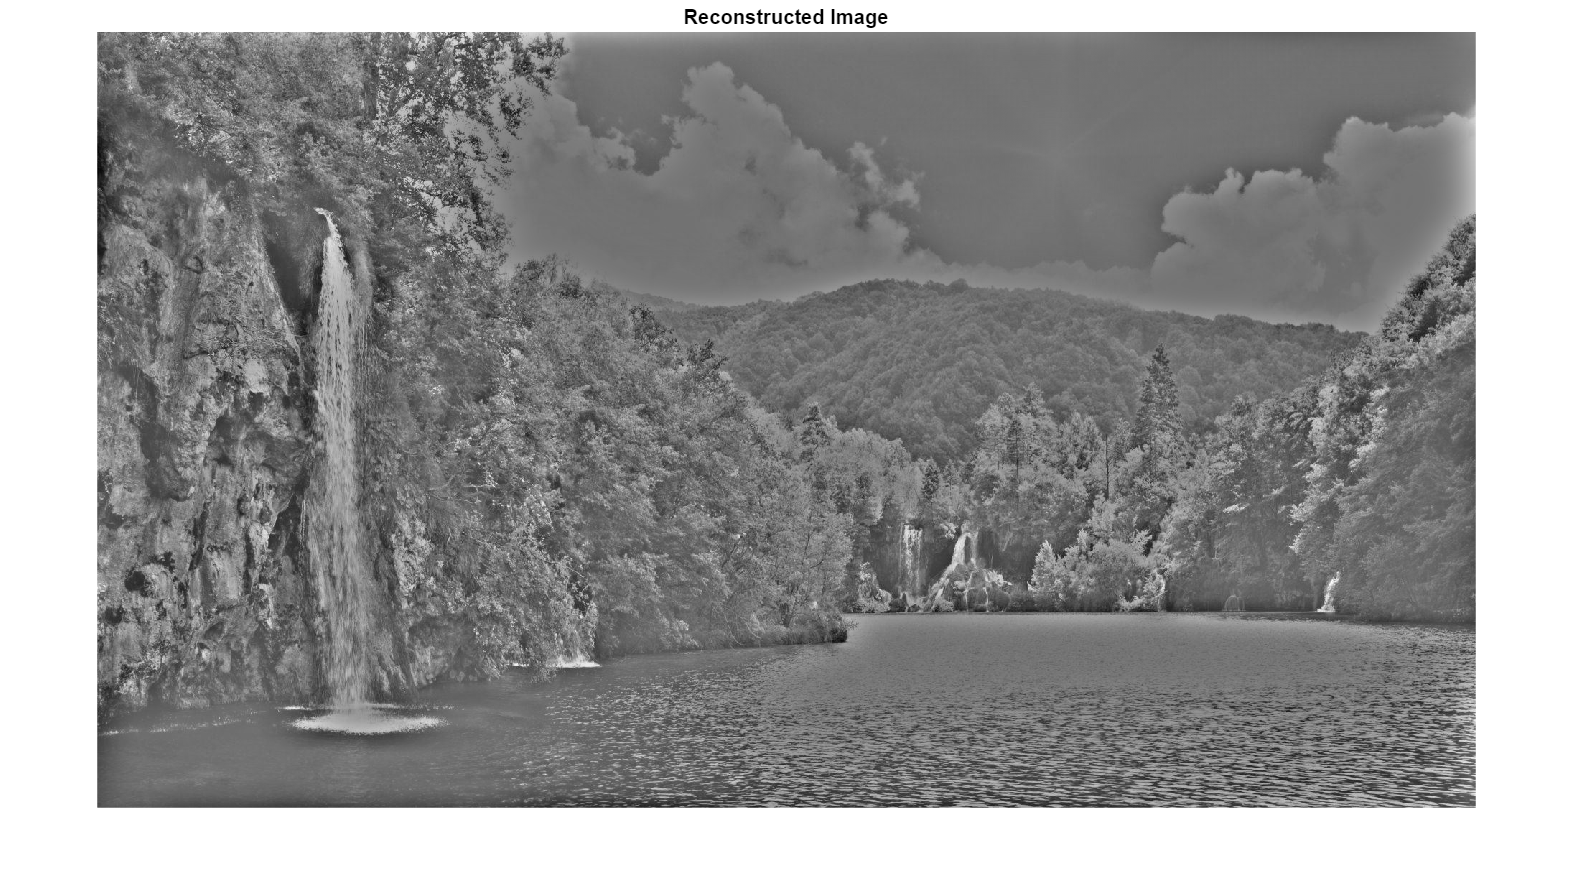

% Reconstruct the image from the new Fourier coefficient matrix
% Shifting back to original by using Inverse Fourier transform
ff_highpass = ifftshift(ff_highpass);
imgR = real(ifft2(ff_highpass)); 

% Displaying the reconstructed image imgR
figure, imshow(imgR, []), title('Reconstructed Image');

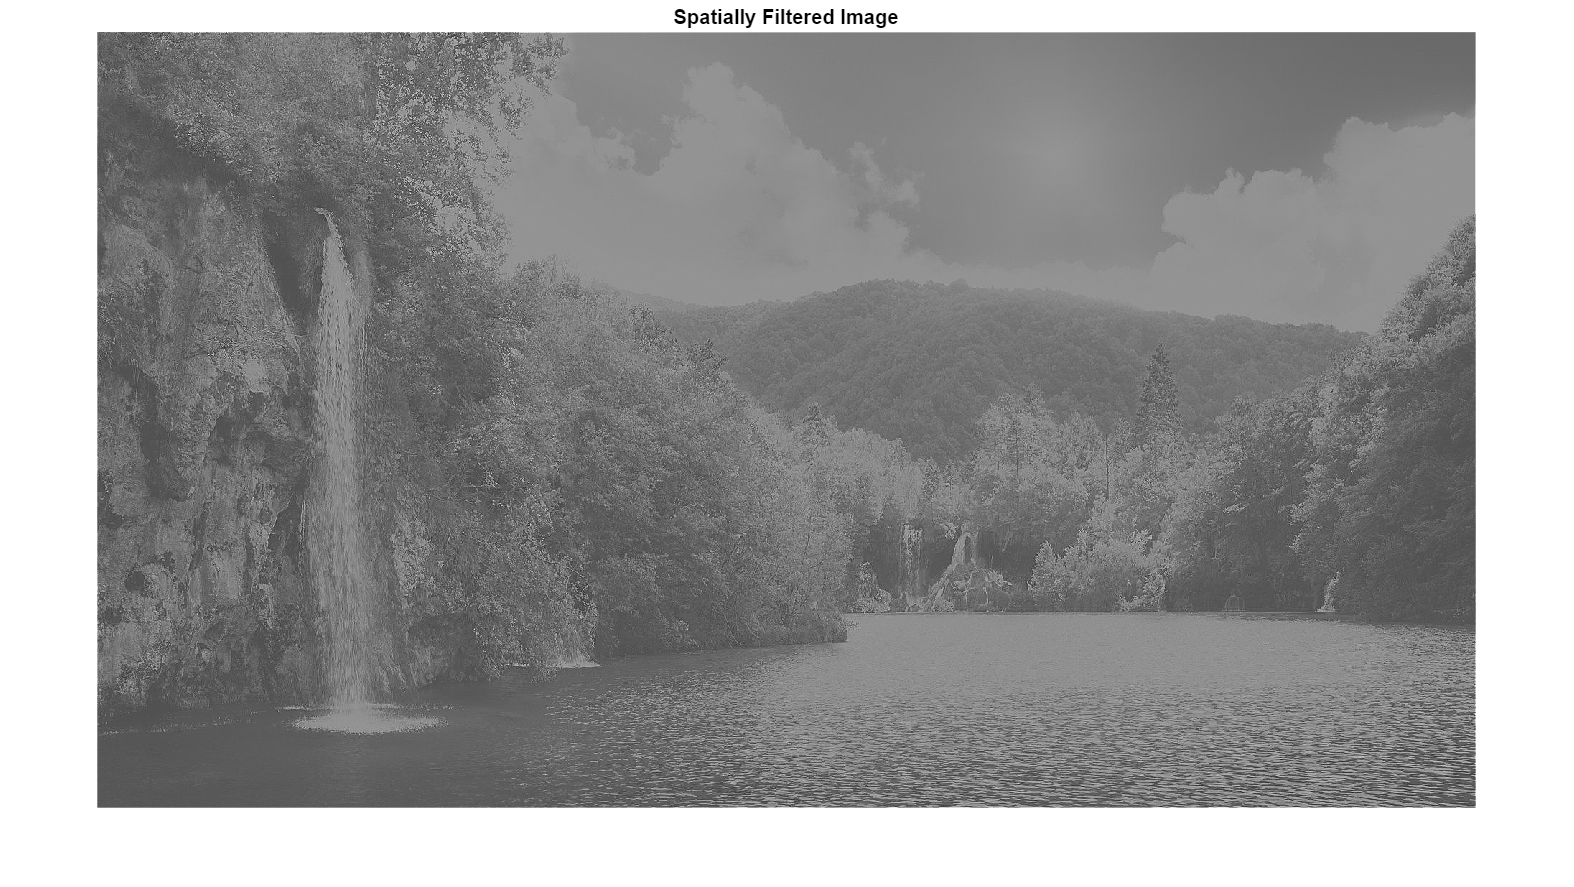

% Construct and apply a spatial filter to img1 to match the reconstructed image imgR 
% Here in this block of code we implement a spacial filter to match the
% reconstrucetd image
% this filter enchances the high frequency components similarly like high
% pass filter
h = fspecial('unsharp');
imgFiltered = imfilter(double(img1), h);

% Display the spatially filtered image
figure, imshow(imgFiltered, []), title('Spatially Filtered Image');

% Compute and display the similarity score between the results of spatial filter and imgR
% Calculate SSIM between filtered image and imgR
ssim_score = ssim(uint8(imgFiltered), uint8(abs(imgR)));
fprintf('SSIM Score: %.4f\n', ssim_score);

SSIM Score: 0.0184


% Calculating Mean Squared Error (MSE) between filtered image and imgR
mse = immse(uint8(imgFiltered), uint8(abs(imgR)));
fprintf('MSE: %.4f\n', mse);

MSE: 21894.0306
